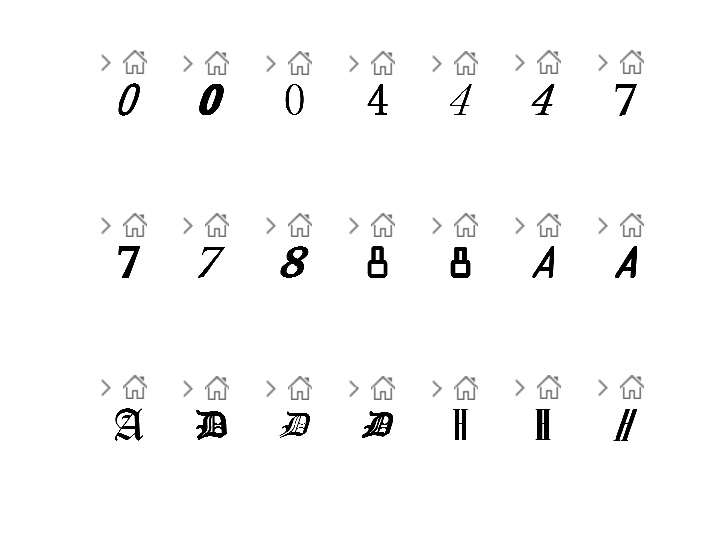

clc; clear;
dsFolder = "p_dataset_26";
subFolder = ["0", "4", "7", "8", "A", "D", "H"];
categories = ["0", "4", "7", "8", "A", "D", "H"];

figure;

rows = 3;
cols = 7;

idx = 1;
for i = 1:length(subFolder)
    folderPath = fullfile(dsFolder, subFolder(i));
    pngFiles = dir(fullfile(folderPath, "*.png"));
    
    for j = 1: 3
        pngFilePath = fullfile(folderPath, pngFiles(idx).name);
        image = imread(pngFilePath);
    
        subplot(rows, cols, idx);
        imshow(image);
        idx = idx+1;
    end
end

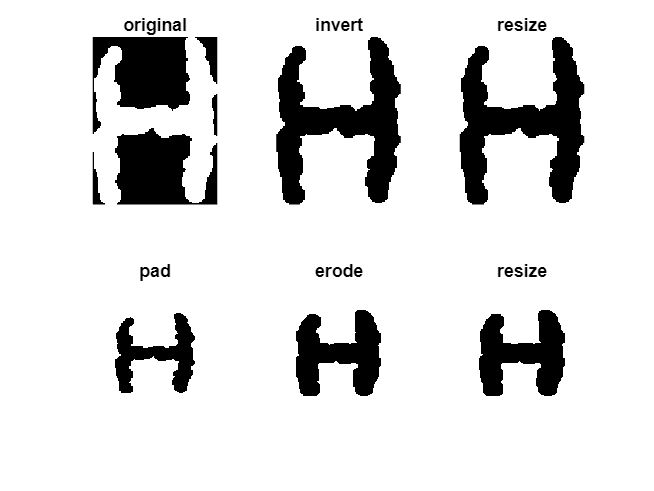

imageHD = 118×88 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1 

% CNN on Characters Classification
charFolder = "Characters";
charValues = ["H", "D", "4", "4", "7", "8", "0", "A", "0", "0"];
charFiles = dir(fullfile(charFolder, "*.png"));

figure;
% Initialize resizedImagesHD with the correct dimensions: [128 128 1 Number_of_Images]
resizedImagesHD = zeros(128, 128, 1, length(charFiles));
paddedSize = [224 224];

for k = 1:1
    charFilePath = fullfile(charFolder, charFiles(k).name);
    imageHD = imread(charFilePath);
    subplot(2, 3, 1);
    imshow(imageHD);
    title("original");

    imageHD = ~imageHD
    subplot(2, 3, 2);
    imshow(imageHD);
    title ("invert");

    resizedImageHD = imresize(imageHD, [128, 128]);
    subplot(2, 3, 3);
    imshow(imageHD);
    title ("resize");

    paddingSize = paddedSize - size(resizedImageHD);
    padTop = floor(paddingSize(1)/2);
    padBottom = ceil(paddingSize(1)/2);
    padLeft = floor(paddingSize(2)/2);
    padRight = ceil(paddingSize(2)/2);
    paddedImage = padarray(resizedImageHD, [padTop, padLeft], 1, 'pre');
    paddedImage = padarray(paddedImage, [padBottom, padRight], 1, 'post');
    subplot(2, 3, 4);
    imshow(paddedImage);
    title ("pad");

    se = strel('disk', 6); 
    erodedImage = imerode(paddedImage, se);
    subplot(2, 3, 5);
    imshow(erodedImage);
    title ("erode");

    processedImage = imresize(erodedImage, [128 128]);
    subplot(2, 3, 6);
    imshow(erodedImage);
    title ("resize");

end